# OGLO notebook 4

hnxj@github

## 1: Time-frequency analysis

aaab = 1;
axab = 2;
aaxb = 3;
aaax = 4;
bbba = 5;
bxba = 6;
bbxa = 7;
bbbx = 8;
rrrr = 9;
rxrr = 10;
rrxr = 11;
rrrx = 12;

order : [area{1-10}, cond{1-12}, sess{1-s*}]

- PSpectrums (X, fs, fLim);

- AAAB vs AAAX, BBBA vs BBBX, RRRR vs RRRX spectral analysis (10 areas)

### MT

xG1 = z{7}{1}{1};
xG2 = z{7}{2}{1};
xG3 = z{7}{3}{1};
xG4 = z{7}{4}{1};

y = squeeze(mean(xG2(1:30,40, :), 1));
[p, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

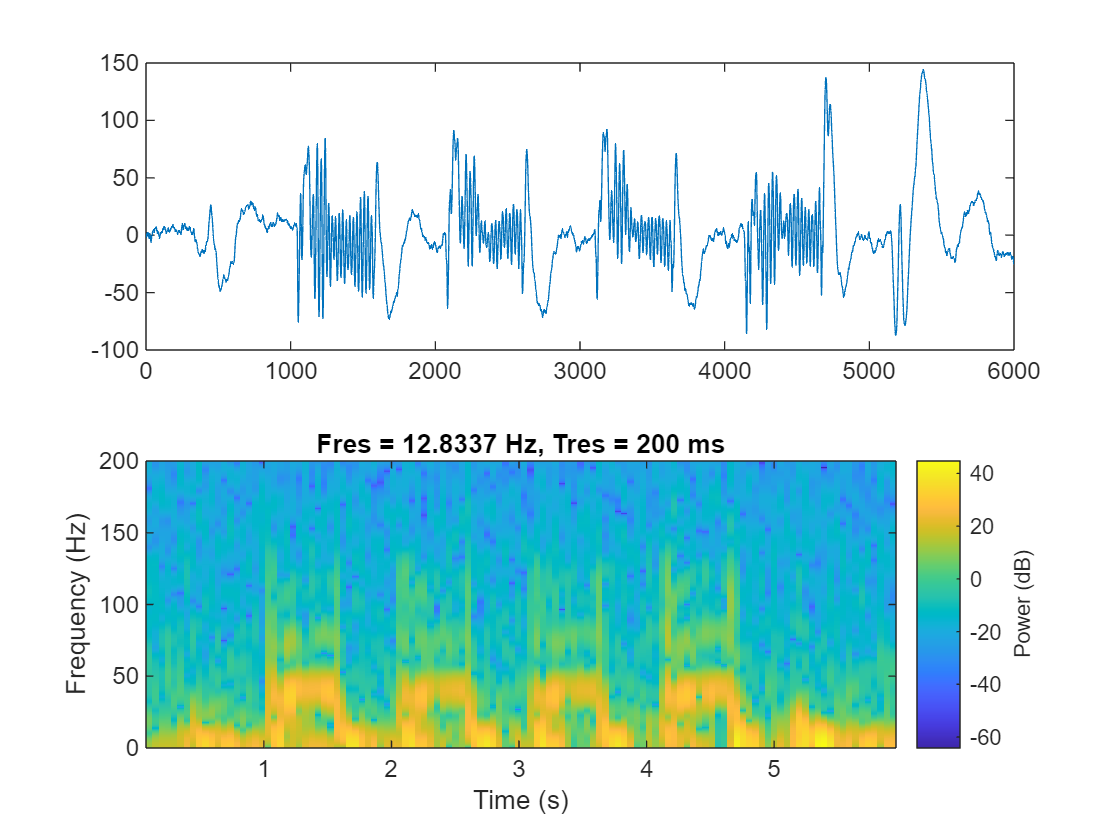

figure;

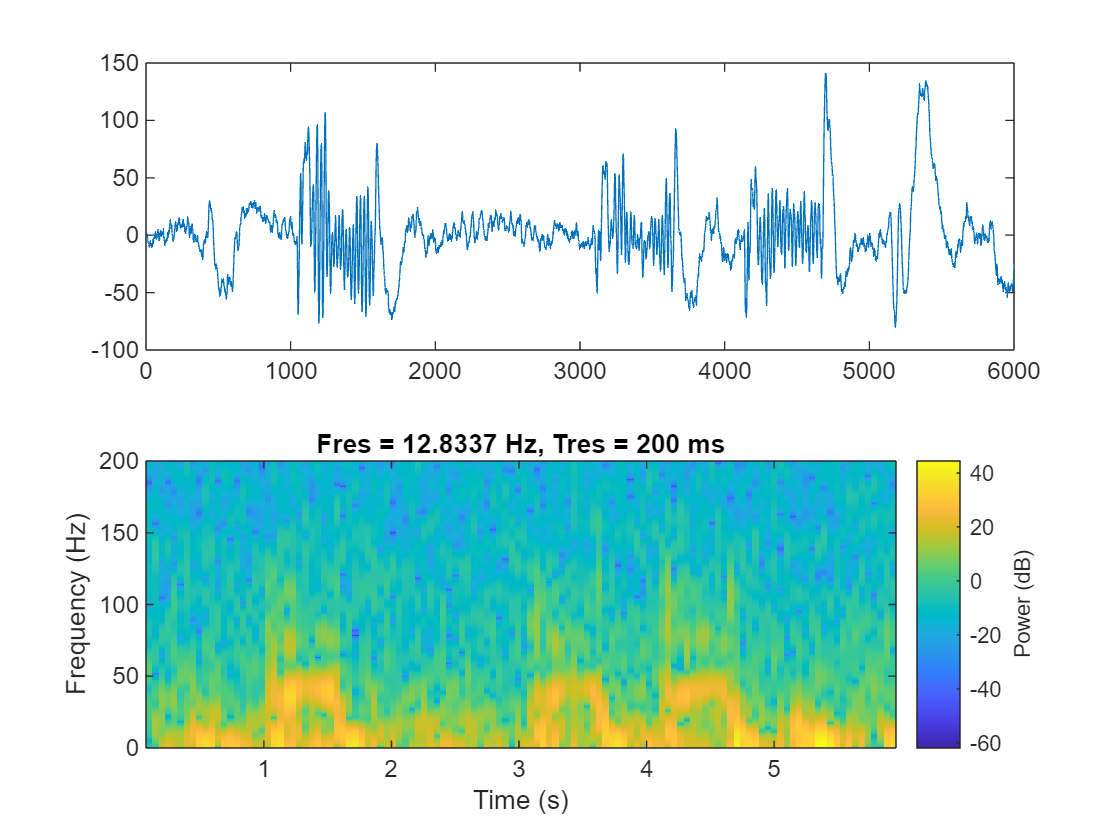

subplot(2, 1, 1);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");

plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
% xline(4.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC");ylim([-7 14]);
% xlim([0.4 5.0]);

subplot(2, 1, 2);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
% xline(4.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT/MST");ylim([-14 20]);
% xlim([0.4 6.0]);

fname = "PFC_MT_Lplot";
print(gcf,'-vector','-dsvg',fname +".svg");

function Y = mvpa_weights(X, G)
% MVPA_WEIGHTS - Perform multivariate pattern analysis (MVPA) using SVM
% Inputs:
%   X - Data matrix (N groups x M channels x T time points)
%   G - Group labels (1 x N group labels)
% Outputs:
%   Y - Weight matrix (N groups x M channels)

% Dimensions
[N, M, T] = size(X);

% Reshape data into 2D matrix for SVM
X_flat = reshape(X, [N, M * T]);

% Initialize weight matrix
Y = zeros(N, M);

% Perform MVPA for each group
for i = 1:N
    % Create binary labels for the current group
    labels = double(G == i);
    labels(labels == 0) = -1; % SVM requires binary labels -1 and 1
    
    % Train linear SVM
    SVMModel = fitcsvm(X_flat, labels, 'KernelFunction', 'linear', ...
                       'Standardize', true, 'ClassNames', [-1, 1]);
    
    % Extract weights for the linear classifier
    beta = SVMModel.Beta; % Coefficients for M*T features
    
    % Reshape weights back to M channels
    Y(i, :) = sum(reshape(beta, [M, T]), 2); % Sum over time dimension
end

end

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG1(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG2(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

## End